Rocket ODE simulation based on the Falcon Heavy Rocket

startingAngle   = 1;      %[°]
tiltingTime     = 20;       %[s]
odeset('AbsTol',1e-6, 'RelTol',1e-6 );

Staging data:

Payload

payload = struct;

Last Stage

stage1      = struct;
stage1.t    = 600;          %[s]    burn time
stage1.m0   = 50000;        %[kg]   starting mass
stage1.mf   = 19000;        %[kg]   final mass
stage1.A    = 91.61;        %[m^2]  front area
stage1.Isp  = 380;          %[s]    specific Impulse
stage1.dm   = (stage1.m0 - stage1.mf)/stage1.t;
stage1.T    = stage1.Isp * 9.81 * stage1.dm

stage1 = struct with fields:
      t: 600
     m0: 50000
     mf: 19000
      A: 91.6100
    Isp: 380
     dm: 51.6667
      T: 192603


Middle Stage

stage2      = struct;
stage2.t    = 400;          %[s]    burn time
stage2.m0   = 171200;       %[kg]   starting mass
stage2.mf   = 65000;        %[kg]   final mass
stage2.A    = 91.61;        %[m^2]  front area
stage2.Isp  = 318;          %[s]    specific Impulse
stage2.dm   = (stage2.m0 - stage2.mf)/stage2.t;
stage2.T    = stage2.Isp * 9.81 * stage2.dm

stage2 = struct with fields:
      t: 350
     m0: 171200
     mf: 65000
      A: 91.6100
    Isp: 318
     dm: 303.4286
      T: 9.4657e+05


Starting Stage

stage3      = struct;
stage3.t    = 130;          %[s]    burn time
stage3.m0   = 525000;       %[kg]   starting mass
stage3.mf   = 207000;       %[kg]   final mass
stage3.A    = 91.61;        %[m^2]  front area
stage3.Isp  = 350.64;       %[s]    specific impulse
stage3.dm   = (stage3.m0 - stage3.mf)/stage3.t;
stage3.T    = stage3.Isp * 9.81 * stage3.dm

stage3 = struct with fields:
      t: 130
     m0: 525000
     mf: 207000
      A: 91.6100
    Isp: 350.6400
     dm: 2.4462e+03
      T: 8.4142e+06


Let's get Launching!

First two seconds (streight up):

u0 = [0; pi/2; 0; 0; stage3.m0];
tSpan = [0, tiltingTime];

[t1, uOut] = ode45(@(t,u) rocketODEstart(u,stage3),tSpan,u0);

v1      = uOut(:,1); v1(end) 

ans = 135.7528

gamma1  = uOut(:,2); gamma1(end)

ans = 1.5708

x1      = uOut(:,3); x1(end)

ans = 0

h1      = uOut(:,4); h1(end)

ans = 1.3244e+03

m1      = uOut(:,5); m1(end)

ans = 4.7608e+05

t1(end)

ans = 20

Now lets add a tiny change in Angle!

gammaStart = pi/2 - pi*startingAngle/180;
u1 = [v1(end); gammaStart; x1(end); h1(end); m1(end)];
tSpan = [t1(end), stage3.t];

[t2, uOut] = ode45(@(t,u) rocketODE(u,stage3),tSpan,u1);

v2      = uOut(:,1); v2(end)

ans = 1.7951e+03

gamma2  = uOut(:,2); gamma2(end)

ans = 1.3992

x2      = uOut(:,3); x2(end)

ans = 1.0405e+04

h2      = uOut(:,4); h2(end)

ans = 8.2734e+04

m2      = uOut(:,5); m2(end)

ans = 2.0700e+05

t2(end)

ans = 130

Next up: Second Stage!

u2 = [v2(end); gamma2(end); x2(end); h2(end); stage2.m0];
tSpan = [t2(end), stage2.t + t2(end)];

[t3, uOut] = ode45(@(t,u) rocketODE(u,stage2),tSpan,u2);

v3      = uOut(:,1); v3(end)

ans = 2.1832e+03

gamma3  = uOut(:,2); gamma3(end)

ans = 0.5427

x3      = uOut(:,3); x3(end)

ans = 2.6633e+05

h3      = uOut(:,4); h3(end)

ans = 5.4897e+05

m3      = uOut(:,5); m3(end)

ans = 6.5000e+04

t3(end)

ans = 480

And now the third! This time with the steering law included

For this, lets first accumulate the relevatn steering data!

steeringData            = struct;
steeringData.gamma0     = gamma3(end);
steeringData.tStart     = t3(end);
steeringData.tEnd       = t3(end) + stage1.t;

And now run it!

u3 = [v3(end); gamma3(end); x3(end); h3(end); stage1.m0];
tSpan = [t3(end), stage1.t + t3(end)];


[t4, uOut] = ode45(@(t,u) rocketODEend(u,stage1,t, steeringData),tSpan,u3);

v4      = uOut(:,1); v4(end)

ans = 4.4729e+03

gamma4  = uOut(:,2); gamma4(end)

ans = 0.0010

x4      = uOut(:,3); x4(end)

ans = 1.7002e+06

h4      = uOut(:,4); h4(end)

ans = 9.6278e+05

m4      = uOut(:,5); m4(end)

ans = 1.9000e+04

t4(end)

ans = 1080

All the simulations are done! Lets get some plots :)

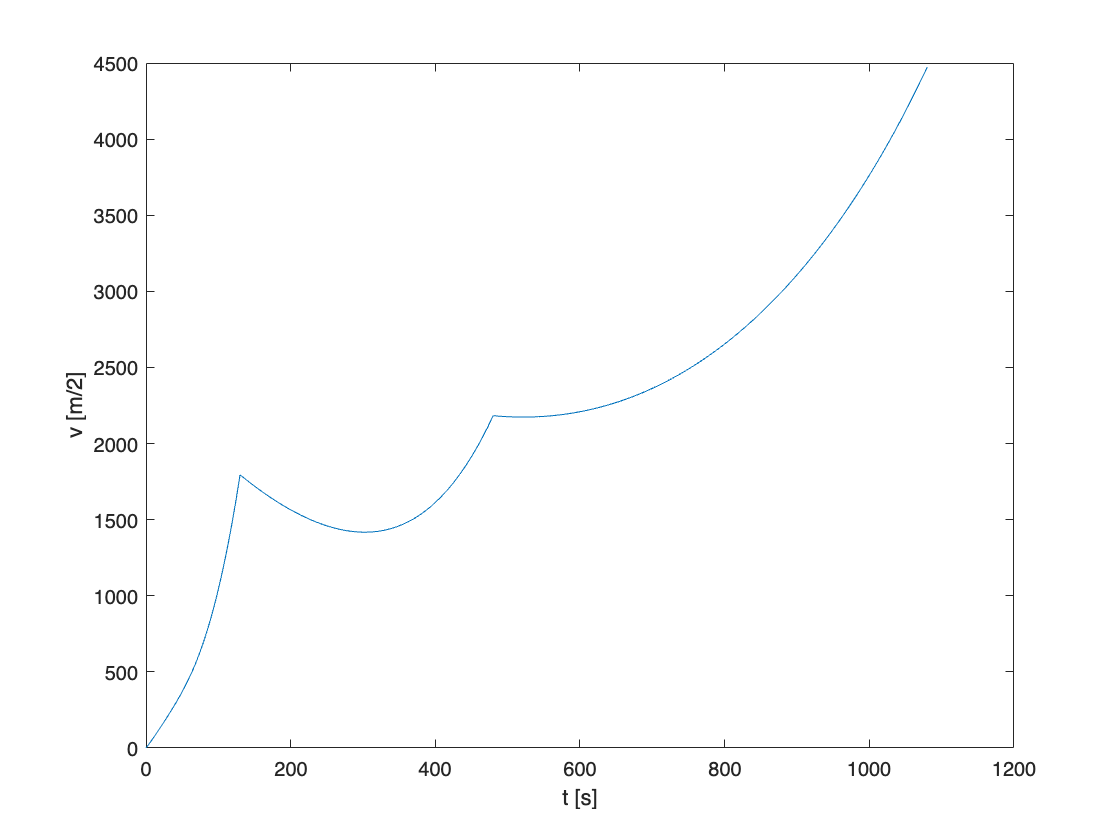

t = [t1; t2; t3; t4];
v = [v1; v2; v3; v4];
x = [x1; x2; x3; x4];
h = [h1; h2; h3; h4];
gamma = [gamma1; gamma2; gamma3; gamma4];
m = [m1; m2; m3; m4];

figure
plot(t, v)
xlabel("t [s]")
ylabel("v [m/2]")

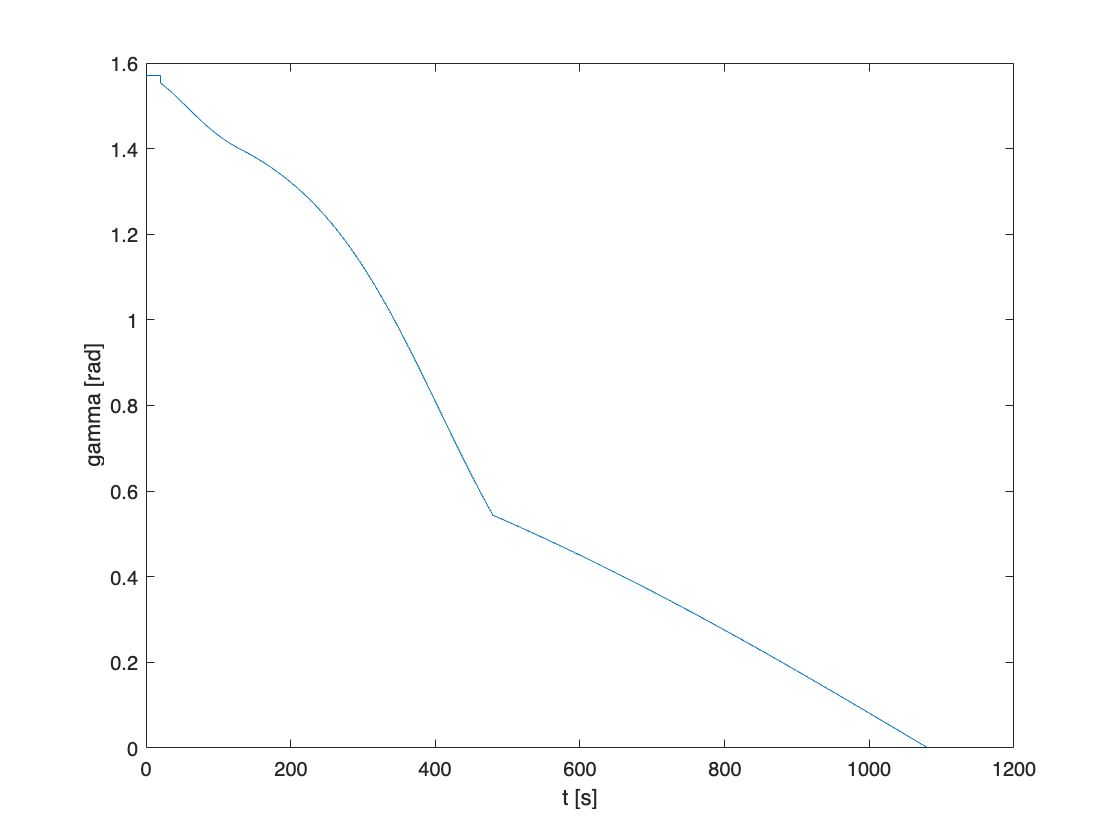


figure
plot(t, gamma)
xlabel("t [s]")
ylabel("gamma [rad]")

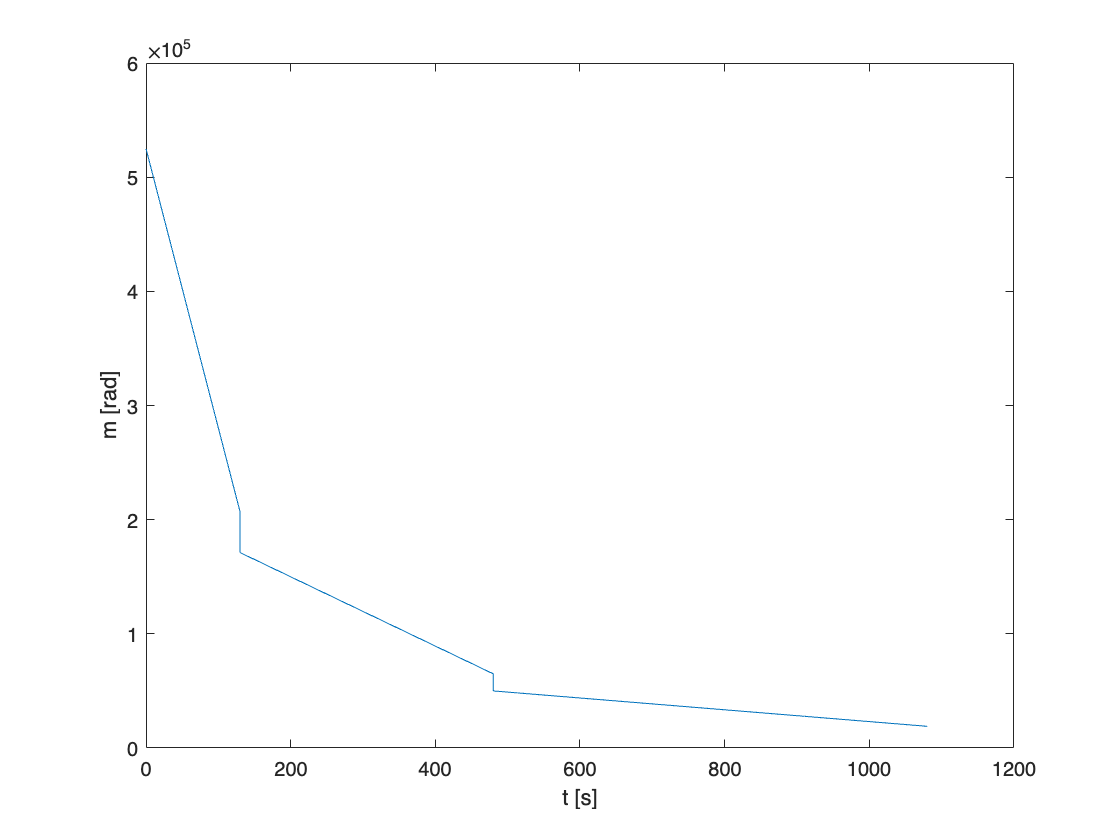


figure
plot(t, m)
xlabel("t [s]")
ylabel("m [rad]")

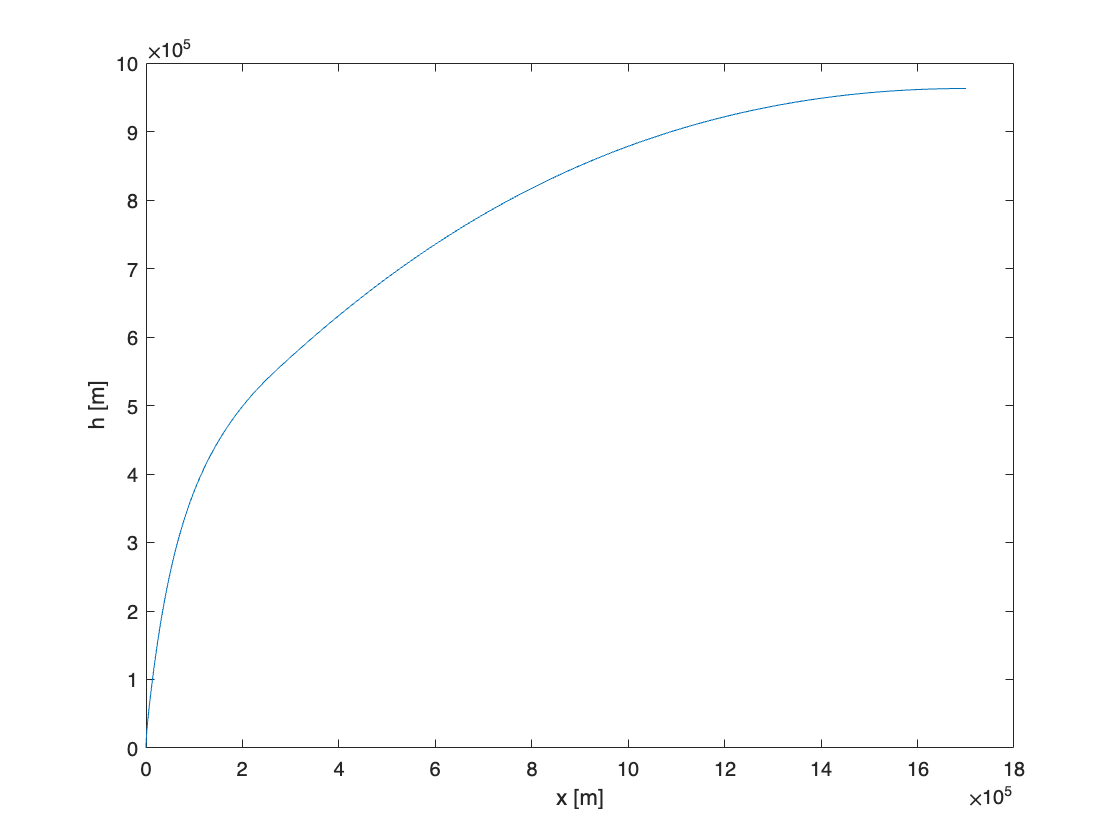


figure
plot(x, h)
xlabel("x [m]")
ylabel("h [m]")